clear; close all; clc;
%C_D_0 = .0075;
e = .9;
rho = 1.0834; % Density at a+*lt
r = convlength(250,"ft","m");
%W_MGTO = 7354.9875; % Maximum Gross Takeoff Weight (N) (DG-1000)
W_MGTO = 700*9.81; % Maximum Gross Takeoff Weight (N) (our aircraft)
b = 20; % wingspan (m)
%c = .85; % cord (m)
% A = 29; % apect ratio (~)
% c = b/A; % cord (m)
% S = b*c;
C_L_max = 2.5; % flapped
%C_L_max = 1.4; % unflapped

W2S_plot_max = 1000

W2S_plot_max = 1000


%A = b^2/S; % apect ratio (~)
syms Aspect


% drag polar estimation
% confirm c_f value form DG-1000
S_wet_fuse_DG1000 = 19.4; % wetted area of fuselage (m)
S_wet_wing_DG1000 = 34.5; % wetted area of fuselage (m)
S_wet_DG1000 = S_wet_fuse_DG1000 + S_wet_wing_DG1000; % total wetted area (m)
c_f = .00245;
f_DG1000 = EquivalentParasiteArea(c_f, S_wet_DG1000);
S_DG100 = 17.53;
C_D_0_DG1000 = DragCoefficientZeroLift(f_DG1000, S_DG100);


% now generate C_D_0 as a function of aspect ratio

% compute wetteed area
S = b^2/Aspect; % compute planform area
S_wet_wing = S_wet_wing_DG1000 * S / S_DG100; % find wing wetted area
S_wet = S_wet_fuse_DG1000 + S_wet_wing; % find total wetted area
%get C_D_0
f = EquivalentParasiteArea(c_f, S_wet); % find equivalent prasite area
C_D_0 = DragCoefficientZeroLift(f, S); % get Parasite Drag
C_D_0 = C_D_0 +.008 % morphing wing variant (from morphing du-89 paper)

$$C\_D\_0 = \frac{6694369541209381\,10^{\frac{\log\left(\frac{32664723271291869375}{3854887766982656\,\mathrm{Aspect}}+\frac{73471957271079683}{351843720888320}\right)}{\log\left(10\right)}-\frac{1470948232708613}{562949953421312}}\,\mathrm{Aspect}}{28823037615171174400}+\frac{1}{125}$$


% Tradeable: L/D = 30 at no less that 50kts
L2D = 30    

L2D = 30

V = convvel(50,"kts","m/s")

V = 25.7222

W2S = W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspect, e, rho)

$$W2S = \begin{array}{l} \left(\begin{array}{c} -\frac{47184744083837325284889993244368183\,\mathrm{Aspect}\,\left(\sigma_{1}-\frac{3991211251234741}{2251799813685248}\right)}{4951760157141521099596496896000000}\\ \min\left(\left[\frac{985180126902579}{1099511627776},\frac{47184744083837325284889993244368183\,\mathrm{Aspect}\,\left(\sigma_{1}+\frac{3991211251234741}{2251799813685248}\right)}{4951760157141521099596496896000000}\right],\left[\right],2,\text{"omitnan"},\mathrm{Aspect}\notin \mathbb{R}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{10\,\left(\frac{60249325870884429\,10^{\frac{\log\left(\frac{32664723271291869375}{3854887766982656\,\mathrm{Aspect}}+\frac{73471957271079683}{351843720888320}\right)}{\log\left(10\right)}-\frac{1470948232708613}{562949953421312}}\,\mathrm{Aspect}}{72057594037927936}-\frac{9\,\pi \,\mathrm{Aspect}}{10}+\frac{144}{5}\right)}{9\,\mathrm{Aspect}}} \end{array}$$


fplot(W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspect, e, rho), [0,50])
view([90,-90]); hold on

% Objective: L/D = 25 at no less that 70kts
L2D = 25

L2D = 25

V = convvel(70,"kts","m/s")

V = 36.0111

W2S = W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspect, e, rho)

$$W2S = \begin{array}{l} \left(\begin{array}{c} -\frac{1109785180851853711683772280175997929\,\mathrm{Aspect}\,\left(\sigma_{1}-\frac{3991211251234741}{2251799813685248}\right)}{49517601571415210995964968960000000}\\ \min\left(\left[\frac{7723812194916219}{4398046511104},\frac{1109785180851853711683772280175997929\,\mathrm{Aspect}\,\left(\sigma_{1}+\frac{3991211251234741}{2251799813685248}\right)}{49517601571415210995964968960000000}\right],\left[\right],2,\text{"omitnan"},\mathrm{Aspect}\notin \mathbb{R}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{10\,\left(\frac{167359238530234525\,10^{\frac{\log\left(\frac{32664723271291869375}{3854887766982656\,\mathrm{Aspect}}+\frac{73471957271079683}{351843720888320}\right)}{\log\left(10\right)}-\frac{1470948232708613}{562949953421312}}\,\mathrm{Aspect}}{288230376151711744}-\frac{9\,\pi \,\mathrm{Aspect}}{10}+20\right)}{9\,\mathrm{Aspect}}} \end{array}$$


syms Aspect
fplot(W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspect, e, rho), [0,50])
view([90,-90])

% Threshold: L/D = 25 at no less that 45kts
L2D = 25

L2D = 25

V = convvel(45,"kts","m/s")

V = 23.1500

W2S = W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspect, e, rho)

$$W2S = \begin{array}{l} \left(\begin{array}{c} -\frac{229317856247449389209554039280789691\,\mathrm{Aspect}\,\left(\sigma_{1}-\frac{3991211251234741}{2251799813685248}\right)}{24758800785707605497982484480000000}\\ \min\left(\left[\frac{797995902791089}{1099511627776},\frac{229317856247449389209554039280789691\,\mathrm{Aspect}\,\left(\sigma_{1}+\frac{3991211251234741}{2251799813685248}\right)}{24758800785707605497982484480000000}\right],\left[\right],2,\text{"omitnan"},\mathrm{Aspect}\notin \mathbb{R}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{10\,\left(\frac{167359238530234525\,10^{\frac{\log\left(\frac{32664723271291869375}{3854887766982656\,\mathrm{Aspect}}+\frac{73471957271079683}{351843720888320}\right)}{\log\left(10\right)}-\frac{1470948232708613}{562949953421312}}\,\mathrm{Aspect}}{288230376151711744}-\frac{9\,\pi \,\mathrm{Aspect}}{10}+20\right)}{9\,\mathrm{Aspect}}} \end{array}$$

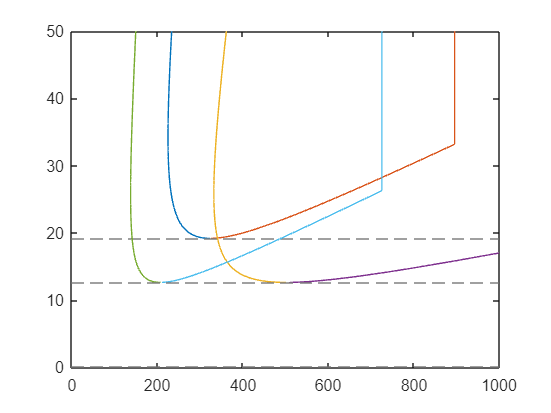


syms Aspect
fplot(W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspect, e, rho), [0,50])
view([90,-90]); xlim([0,50]); ylim([0,1000]);


% an atempt to do it in terms of W2S
figure;
Aspects = linspace(1,50,100);
C_D_0 = double(subs(C_D_0, Aspect, Aspects))

C_D_0 =     0.0129    0.0130    0.0130    0.0131    0.0132    0.0132    0.0133    0.0133    0.0134    0.0134    0.0135    0.0136    0.0136    0.0137    0.0137    0.0138    0.0139    0.0139    0.0140    0.0140    0.0141    0.0141    0.0142    0.0143    0.0143    0.0144    0.0144    0.0145    0.0146    0.0146    0.0147    0.0147    0.0148    0.0148    0.0149    0.0150    0.0150    0.0151    0.0151    0.0152    0.0153    0.0153    0.0154    0.0154    0.0155    0.0156    0.0156    0.0157    0.0157    0.0158


W2Ss_ld25_v45 = W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspects, e, rho);
plot(W2Ss_ld25_v45, Aspects);

ylim([0,50]); xlim([0,1000]);

W2Ss_ld25_v70 = W2S_LiftToDragAtSpeed(L2D, convvel(70,"kts","m/s"), C_D_0, C_L_max, Aspects, e, rho);
W2Ss_ld30_v50 = W2S_LiftToDragAtSpeed(30, convvel(50,"kts","m/s"), C_D_0, C_L_max, Aspects, e, rho);
hold on; plot(W2Ss_ld25_v70, Aspects); plot(W2Ss_ld30_v50, Aspects);


S_possible = b^2 ./ Aspects;
W2S_possible = W_MGTO ./ S_possible;
plot(W2S_possible, Aspects,"m");

%limit the wingloadings by the stall constriant (steady state glide limit)
syms wingloading
stall_70kts = double(solve(wingloading*2/(rho*convvel(70,"kts","m/s")^2) == C_L_max, wingloading));
stall_45kts = double(solve(wingloading*2/(rho*convvel(45,"kts","m/s")^2) == C_L_max, wingloading));
stall_50kts = double(solve(wingloading*2/(rho*convvel(50,"kts","m/s")^2) == C_L_max, wingloading));

W2Ss_ld25_v70(2,:) = min(W2Ss_ld25_v70(2,:),stall_70kts);
W2Ss_ld25_v45(2,:) = min(W2Ss_ld25_v45(2,:),stall_45kts);
W2Ss_ld30_v50(2,:) = min(W2Ss_ld30_v50(2,:),stall_50kts);

%plot stall lines
xline(stall_70kts,"-","W2S max for v = 70kts","Color",[1,1,0])
xline(stall_45kts,"-","W2S max for v = 45kts","Color",[1,0,0])
xline(stall_50kts,"-","W2S max for v = 50kts","Color",[1,1,0])

% contained region
include_ld25_v70 = [W2Ss_ld25_v70(1,:), fliplr(W2Ss_ld25_v70(2,:))];
include_v45 = [W2Ss_ld25_v45(1,:), fliplr(W2Ss_ld25_v45(2,:))];
include_ld30_v50 = [W2Ss_ld30_v50(1,:), fliplr(W2Ss_ld30_v50 (2,:))];
inBetween = [Aspects, fliplr(Aspects)];
% fill(include_ld25_v70, inBetween, [0,1,0],"FaceAlpha",.10)
% fill(include_v45, inBetween, [0,1,0],"FaceAlpha",.10)
% fill(include_ld30_v50, inBetween, [0,1,0],"FaceAlpha",.10)
hold on

% upper bound
exclude_ld25_v70_upper = [zeros(size(Aspects)), fliplr(W2Ss_ld25_v70(1,:))];
exclude_ld25_v45_upper = [zeros(size(Aspects)), fliplr(W2Ss_ld25_v45(1,:))];
exclude_ld30_v50_upper = [zeros(size(Aspects)), fliplr(W2Ss_ld30_v50(1,:))];
fill(exclude_ld25_v70_upper, inBetween, [1,1,0],"FaceAlpha",.20);

fill(exclude_ld30_v50_upper, inBetween, [1,1,0],"FaceAlpha",.20);

fill(exclude_ld25_v45_upper, inBetween, [1,0,0],"FaceAlpha",.30);


%lower bounds
exclude_ld25_v70_lower = [W2S_plot_max* ones(size(Aspects)), fliplr(W2Ss_ld25_v70(2,:))];
exclude_ld30_v50_lower = [W2S_plot_max* ones(size(Aspects)), fliplr(W2Ss_ld30_v50(2,:))];
exclude_ld25_v45_lower = [W2S_plot_max* ones(size(Aspects)), fliplr(W2Ss_ld25_v45(2,:))];

fill(exclude_ld25_v70_lower,inBetween, [1,1,0], "FaceAlpha",.20);

fill(exclude_ld30_v50_lower,inBetween, [1,1,0], "FaceAlpha",.20);

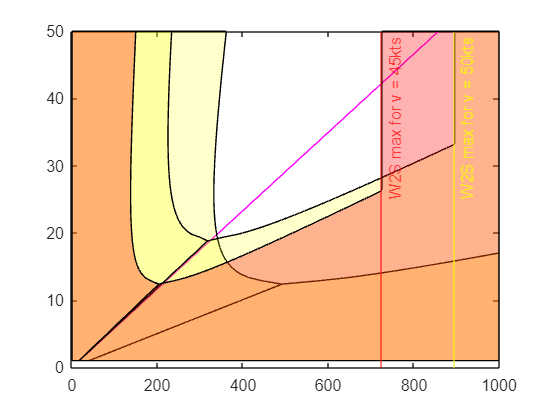

fill(exclude_ld25_v45_lower,inBetween, [1,0,0], "FaceAlpha",.30);


% area(W2Ss_ld25_v70(2,:), Aspects, 0, "FaceAlpha",.20, "FaceColor",[1,1,0]);
% area(W2Ss_ld30_v50(2,:), Aspects, "FaceAlpha",.20, "FaceColor",[1,1,0]);
% area(W2Ss_ld25_v45(2,:), Aspects, "FaceAlpha",.30, "FaceColor",[1,0,0]);

% drags = linspace(.0025,.0075,100)
% for i = 1:length(drags)
%     syms Aspect
%     fplot(W2S_LiftToDragAtSpeed(L2D, V, C_D_0, Aspect, e, rho), [0,50])
%     view([90,-90])
%     pause(.1)
% end


## Sink Rate Requirements

% here I will now plot requirements imposed by sink rates given in the spec
V

V = 23.1500